# Баєсiвський пiдхiд в криптоаналiзi: побудова i дослiдження детермiнiстичної та стохастичної вирiшуючих функцiй

### Варіант 4

### Мета роботи

Ознайомлення з принципами баєсiвського пiдходу в криптоаналiзi: побудова вирiшуючих функцiй для моделей схем шифрування та криптоаналiз моделей шифрiв за допомогою програмної реалiзацiї; порiвняння детерміністичної та стохастичної вирiшуючих функцiй.

### Задача

Маючи відомі розподіли відкритих текстів $\Pr \left\lbrace M\right\rbrace$ та ключів $\Pr \left\lbrace K\right\rbrace$задані в файлі "prob_04.csv", а також правило шифрування $\mathrm{Enc}:\;K\times M\longrightarrow C$ задане таблицею в файлі "table_04.csv", побудувати оптимальні: 

- Детерміністичну вирішуючу функцію;

- Стохастичну вирішуючу функцію.

Обчислити та порівняти середнє значення втрати для побудованих вирішуючих функцій.

### Хід роботи

Основні кроки для вирішення поставленої задачі:

- Із заданих розподілів та функції шифрування обчислити сумісний розподіл відкритих текстів та шифротекстів $\Pr \left\lbrace M,C\right\rbrace$.

- Маючи розподіл $\Pr \left\lbrace M,C\right\rbrace$, обчислити оптимальні вирішуючі функції $\delta_{\mathrm{stochastic}}$ та  $\delta_{\mathrm{deterministic}}$.

- Для побудованих функцій обчислити середнє значення втрат $l\left(\delta \right)$.

### Код та результати

sympref('MatrixWithSquareBrackets', true);
%sympref('FloatingPointOutput', true);
format short
N = 20;

**Початкові дані.** Зчитуємо таблиці із файлів та виведемо отримані розподіли і таблицю.

ProbsT = table2array(readtable('prob_04.csv'));
EncT = (table2array(readtable('table_04.csv')) + 1);
prob_K = ProbsT(2, :);
prob_M = ProbsT(1, :);

Розподіл на множині ключів:

fprintf('Pr{K=%d} =\t%.3f\n', [1:N; prob_K]) % Розподіл ключів

Pr{K=1} =	0.050
Pr{K=2} =	0.050
Pr{K=3} =	0.050
Pr{K=4} =	0.050
Pr{K=5} =	0.050
Pr{K=6} =	0.050
Pr{K=7} =	0.050
Pr{K=8} =	0.050
Pr{K=9} =	0.050
Pr{K=10} =	0.050
Pr{K=11} =	0.050
Pr{K=12} =	0.050
Pr{K=13} =	0.050
Pr{K=14} =	0.050
Pr{K=15} =	0.050
Pr{K=16} =	0.050
Pr{K=17} =	0.050
Pr{K=18} =	0.050
Pr{K=19} =	0.050
Pr{K=20} =	0.050


На множині відкритих текстів:

fprintf('Pr{M=%d} =\t%.3f\n', [1:N; prob_M]) % Розподіл відкритих текстів

Pr{M=1} =	0.090
Pr{M=2} =	0.090
Pr{M=3} =	0.090
Pr{M=4} =	0.090
Pr{M=5} =	0.040
Pr{M=6} =	0.040
Pr{M=7} =	0.040
Pr{M=8} =	0.040
Pr{M=9} =	0.040
Pr{M=10} =	0.040
Pr{M=11} =	0.040
Pr{M=12} =	0.040
Pr{M=13} =	0.040
Pr{M=14} =	0.040
Pr{M=15} =	0.040
Pr{M=16} =	0.040
Pr{M=17} =	0.040
Pr{M=18} =	0.040
Pr{M=19} =	0.040
Pr{M=20} =	0.040


А також таблицю шифрування:

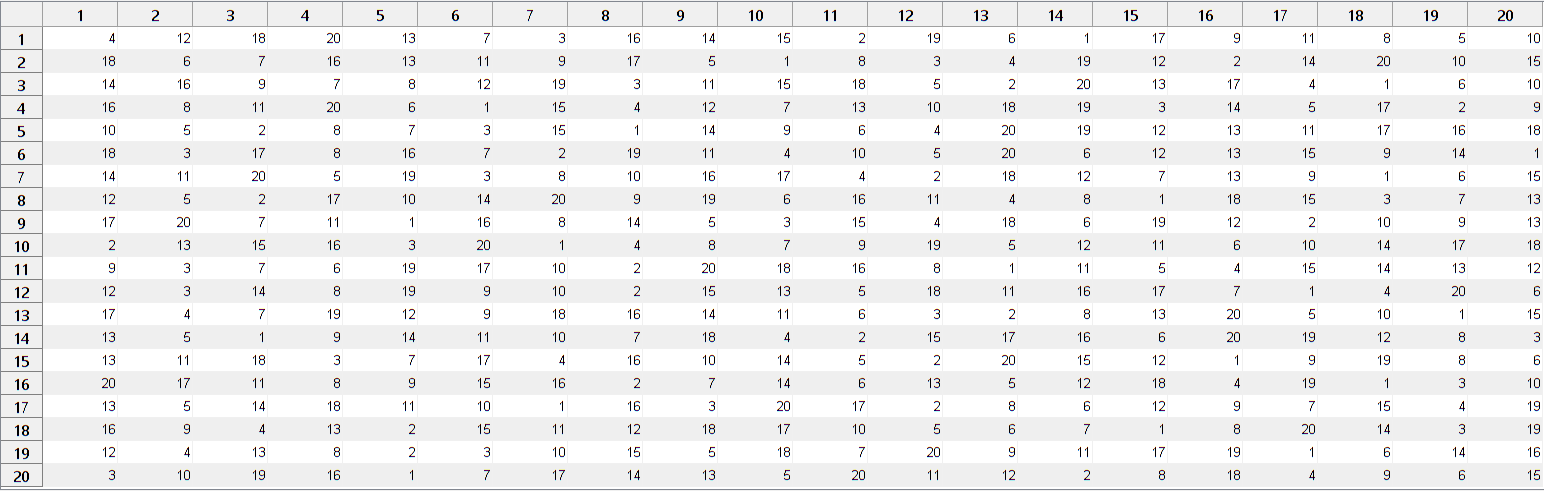

h = figure(1);
u = uitable(h, "Data", uint32(EncT));
table_extent = get(u,'Extent');
set(u,'Position',[1 1 table_extent(3) table_extent(4)])
figure_size = get(h,'outerposition');
desired_fig_size = [figure_size(1) figure_size(2) table_extent(3)+13 table_extent(4)+39];
set(h,'outerposition', desired_fig_size);

**Сумісний розподіл. **Із теоретичних викладок, наведених в документі лабораторної, можна сказати, що побудова оптимальної вирішуючої функції (як детерміністичної, так і стохастичної) зводиться до пошуку максимально ймовірних відкритих текстів для кожного шифротексту, тобто:

$\forall \;C:\;\;$знайти такі $M_{\max }$ що $\;M_{\max } ={\mathrm{argmax}}_{m\in M} \;\Pr \left\lbrace m\;|\;C\right\rbrace$

***Зауваження.  ***Замість умовного розподілу $\Pr \left\lbrace M\;|\;C\right\rbrace$ можна розглядати сумісний – $\Pr \left\lbrace M,\;C\right\rbrace$, оскільки 

$\Pr \left\lbrace M\;|\;C\right\rbrace =\frac{\Pr \left\lbrace M,\;C\right\rbrace }{\Pr \left\lbrace C\right\rbrace }$,

і домножання кожного рядку на $\Pr \left\lbrace C\right\rbrace$ не змінює максимумів.

Сумісний розподіл обчислимо як:


$$\sum_{K:\;\;\mathrm{Enc}\left(K,M\right)=C} \Pr \left\lbrace M\right\rbrace \Pr \left\lbrace K\right\rbrace$$


prob_MC = zeros(N);

for M = 1:N
    for K = 1:N
        C = EncT(K, M);
        prob_MC(C, M) = prob_MC(C, M) + (prob_M(M) * prob_K(K));
    end
end

Відповідно матриця сумісного розподілу $M$ та $C$ має вигляд:

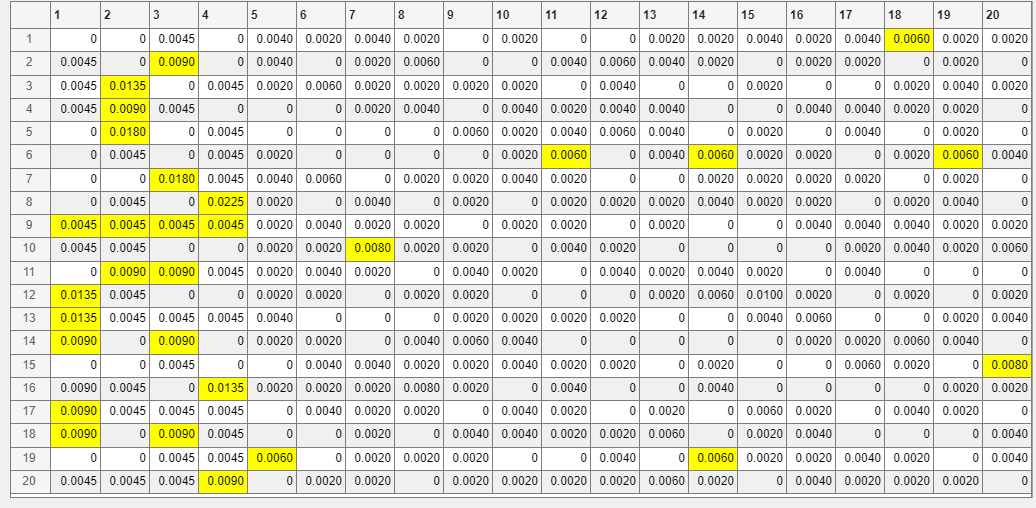

fig = uifigure;
fig.Position = [10 10 1035 507];
uit = uitable(fig, "Data", prob_MC, 'ColumnWidth', 'fit');
uit.Position = [11 11 1023 497]; 
[row, col] = find(prob_MC >= max(prob_MC, [], 2));
s = uistyle('BackgroundColor','yellow');
addStyle(uit, s,'cell', [row, col])

де жовтим позначені максимальні значення в кожному рядку (тобто максимально ймовірні відкиті тексти для кожного шифротексту).

**Побудова вирішуючих функцій. **

[max_probs, indxs] = max(prob_MC, [], 2);
det_foonk11 = false(N);

det_foonk11(sub2ind(size(det_foonk11), 1:N, indxs')) = 1;

sum(~det_foonk11 .* prob_MC, 'all')

ans = 0.7860

stoochastic_foonk1 = (prob_MC == max_probs);
stoochastic_foonk1 = stoochastic_foonk1 ./ sum(stoochastic_foonk1, 2);

det_foonk1 = dictionary(1:N, indxs')

det_foonk1 =   dictionary (double ⟼ double) with 20 entries:

    1  ⟼ 18
    2  ⟼ 3
    3  ⟼ 2
    4  ⟼ 2
    5  ⟼ 2
    6  ⟼ 11
    7  ⟼ 3
    8  ⟼ 4
    9  ⟼ 1
    10 ⟼ 7
    11 ⟼ 2
    12 ⟼ 1
    13 ⟼ 1
    14 ⟼ 1
    15 ⟼ 20
    16 ⟼ 4
    17 ⟼ 1
    18 ⟼ 1
    19 ⟼ 5
    20 ⟼ 4


stoochastic_foonk1

stoochastic_foonk1 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    1.0000         0         0
         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

sum((ones(N) - stoochastic_foonk1) .* prob_MC, 'all')

ans = 0.7860

max_prob_M = cell(N, 1);
for i = 1:N
    max_prob_M(i) = {find(prob_MC(i, :) == max_probs(i))};
end

max_prob_M

max_prob_M = 20×1 cell array
    {[      18]}
    {[       3]}
    {[       2]}
    {[       2]}
    {[       2]}
    {[11 14 19]}
    {[       3]}
    {[       4]}
    {[ 1 2 3 4]}
    {[       7]}
    {[     2 3]}
    {[       1]}
    {[       1]}
    {[     1 3]}
    {[      20]}
    {[       4]}


det_foonk2 = @(C) max_prob_M{C}(1);
stoochastic_foonk2 = @(C) randsample(max_prob_M{C}, 1);

det_foonk2(14)

ans = 1

stoochastic_foonk2(14)

ans = 1